% Defining parameters

N = 5; % Number of observations
A = 1; % True value of A
sigma2 = 0.001; % Variance of WGN
f0 = 0.25; % True value of fundamental frequency
phi = pi/3; % True value of Phi
numMonteCLoops = 1E5; % Number of monte carlo loops

% Initiate estimates array 
estimate_f0 = ones(1,numMonteCLoops)*NaN;
estimate_A = ones(1,numMonteCLoops)*NaN;
estimate_Phi = ones(1,numMonteCLoops)*NaN;

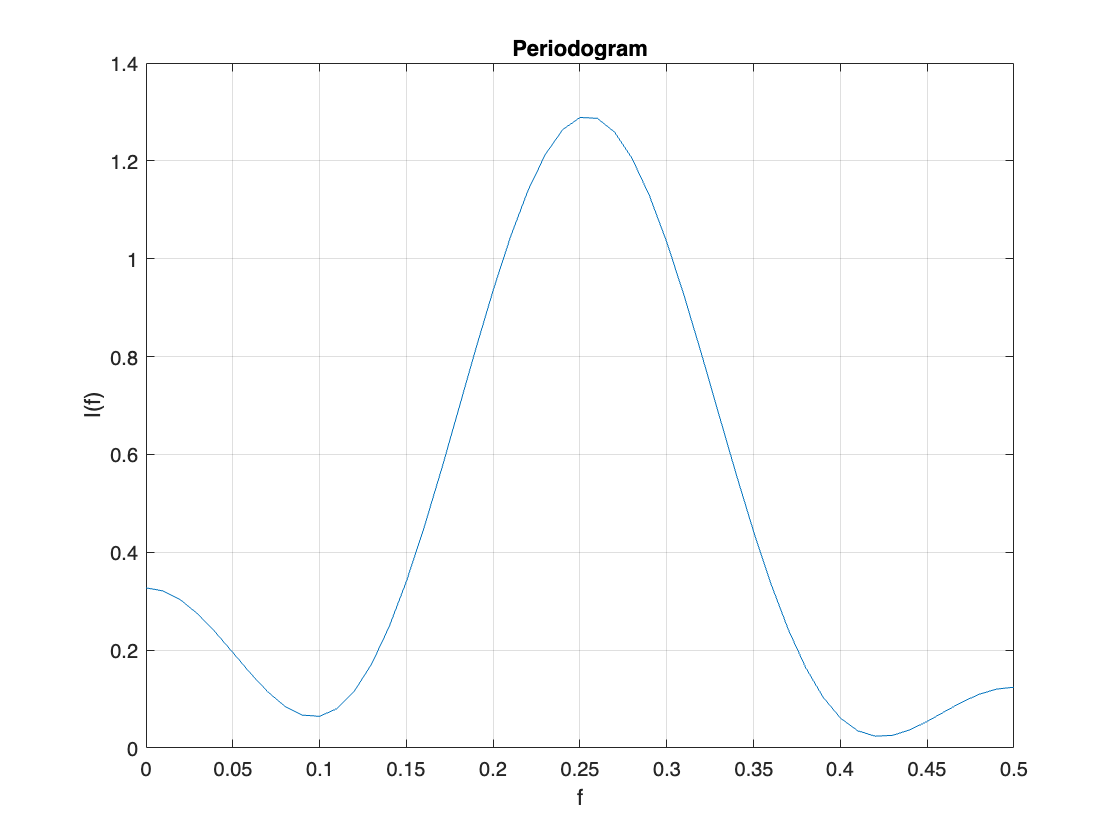

Periodogram for one loop to observe the behavior


% Monte Carlo Loops
for MC=1:numMonteCLoops

    w = randn(1,N)*sqrt(sigma2).*(1:N); % the WGN part
    ang1 = 2*pi*f0.*(1:N);
    ang2 = ang1 + phi;
    x = A*cos(ang2) + w;
    
    % The periogram which is maximized by MLE of f0
    f = 0:0.01:0.5;
    xx = zeros(size(f));
    for n = 1 :5
        xInst = x(n) * exp(-1j * 2 * pi .*f * n);
        xx = xx + xInst;
    end

    If = 0.2* abs(xx).^2;
   
    if MC == 1
 
       % Plot squares_of_absolute_values against f
       plot(f, If);
       xlabel('f');
       ylabel('I(f)');
       title('Periodogram');
       grid on;
       disp('Periodogram for one loop to observe the behavior');
    end

    % Find the arg max of If as in (7.66)
    [max_value, index] = max(If);
    
    % Get the corresponding frequency value
    f0_est = f(index);
    
    
    % calculation of A_est as in (7.66)
    A_est = 0;
    for n = 1 :5
        xInst = x(n) * exp(-1j * 2 * pi *f0_est * n);
        A_est = A_est + xInst;
    end
    A_est = 0.4* abs(A_est);
    
    % calculation of Phi_est (7.66)
    Phi_est_Num = 0;
    Phi_est_Dem = 0;
    for n = 1 :5
        xInst = x(n) *sin(2*pi*f0_est*n);
        Phi_est_Num = Phi_est_Num + xInst;
    
        xInst1 = x(n) *cos(2*pi*f0_est*n);
        Phi_est_Dem = Phi_est_Dem + xInst1;
    end
    
    Phi_est = atan(-1*Phi_est_Num/Phi_est_Dem);

    estimate_f0(MC) = f0_est;
    estimate_A(MC) = A_est;
    estimate_Phi(MC) = Phi_est;

end

% Variance of MLE of f0
std(estimate_f0)^2

ans = 2.3713e-05

% Variance of MLE of A
std(estimate_A)^2

ans = 0.0053

% Variance of MLE of Phi
std(estimate_Phi)^2

ans = 0.0062

%% Defining CRLB Values as per (3.41)
eta = A^2/(2*sigma2);
CRLB_A = 2*sigma2/N;
CRLB_f0 = 12 / (((2*pi)^2)*eta*N*((N^2)-1));
CRLB_phi = (2*(2*N -1)) / (eta*N*(N+1));



if std(estimate_f0)^2 >= CRLB_f0
    disp('The CRLB is satisfied for MLE of f0');
end

The CRLB is satisfied for MLE of f0



if std(estimate_A)^2 >= CRLB_A
    disp('The CRLB is satisfied for MLE of A');
end

The CRLB is satisfied for MLE of A



if std(estimate_Phi)^2 >= CRLB_phi
    disp('The CRLB is satisfied for MLE of Phi');
end

The CRLB is satisfied for MLE of Phi
